## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath_ = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

2.1 Create ASSETCL plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_PlotNames, 'TR', '');

Set up **backtestPortfolio** **Method **properties

none (default) 

%            - rolling_w    (window)

%            - exp_decay    (tau)

%            - crisp        (alpha, z_target)       **NOTE**: z_target options 'mean' or 'latest'

%            - kernel       (h, gamma, z_target)

%            - e_pooling    (alpha, tau_prior, z_target)

%            - ew_ensemble  (alpha, tau_prior, z_target)

%            - cb_ensemble  (alpha, tau_prior, z_target,ensemble_wt_method)

## 3. Setting up HSFP object and Backtest object:

- Need to initialise backtestedPortfolio object (has built in defaults)

-  Initialise HSFPparameters object (has built in defaults)

- Need to provide Returns

- Assign HSFP parameters to backtestPortfolio

- Choose a method (defualt is 'None)

- If method is anything other than 'none' user needs to assign Signals Timetable

test_class1 = backtestedPortfolios;
HSFPparameters_test = HSFPparameters;
test_class1.HSFPparameters = HSFPparameters_test;
test_class1.Returns = M_Ret_TT;
test_class1.Method =  'none';
test_class1.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class1.HRPcashConstriant = 1;
test_class1.MVWts_lb = [0 0 0 0 0.05];
test_class1.MVWts_ub = [1 1 1 1 0.05];
test_class1.RegLambda = 0.005;
% test_class1.PSRbenchmark = "strategyWise";

 test1_bcktest = OOPbacktest_analysis(test_class1)
PerformancePlot(test1_bcktest)

OptControlPlot(test1_bcktest)

Y = test1_bcktest.RollingPerformance.Time;

test1_bcktest =   backtestedPortfolios with properties:

        PortfoliosList: {'EW (CM)'  'MVSR max'  'BalFund (BH)'  'HRP'  'BalFund (CM)'  'ALSI'  'ALBI'  'Cash'}
             AssetList: {'ALB_Index'  'FINI15_Index'  'INDI25_Index'  'RESI20_Index'  'Cash'}
          Attributions: [5×5 table]
    RollingPerformance: [152×8 timetable]
              HSFP_Prs: []
         NumPortfolios: 0
              DataType: "backtestedPortfolios"
         ExcessReturns: [151×5 double]
           GeometricSR: [1.6581 1.5715 1.7454 1.6519 1.8220]
            OptPortWts: {2×5 cell}
    Realised_tsPRet_TT: [152×8 timetable]
          WindowLength: 36
               Returns: [188×6 timetable]
               Signals: [189×1 timetable]
             RegLambda: 0.0050
              MVWts_lb: [0 0 0 0 0.0500]
              MVWts_ub: [1 1 1 1 0.0500]
     HRPcashConstriant: 1
                Method: "none"
        HSFPparameters: [

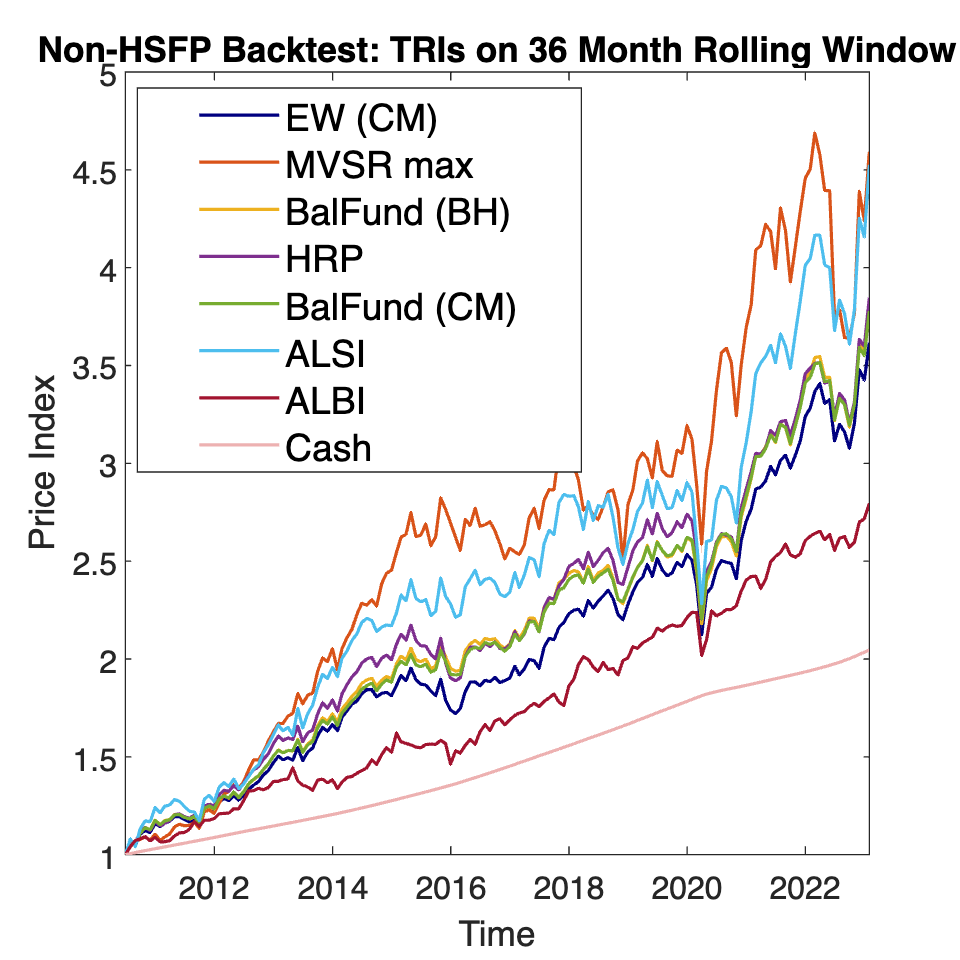

ans =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [1 1 1]
    Position: [100 100 600 600]
       Units: 'pixels'

  Show all properties


Z = [test1_bcktest.OptPortWts{2,4}];

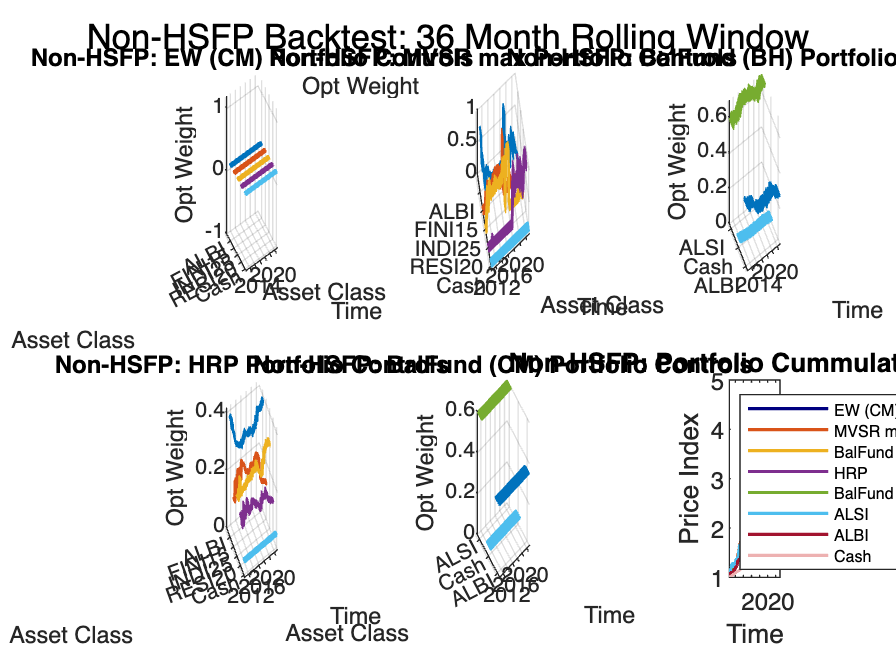

ans =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [1 1 1]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


h = ribbon(Y,Z,0.5);
title(['Optimal Weight Surfaces for ',test1_bcktest.OptPortWts{1,4},' Portfolio'],'FontSize', 16 )

colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue
colormap(colours)
h(1).EdgeColor = "white";
h(2).EdgeColor = "white";
h(3).EdgeColor = "white";
h(4).EdgeColor = "white";
h(5).EdgeColor = "white";
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALB Index','FINI15 Index','INDI25 Index','RESI20 Index','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([57.336 78.226])

test1_bcktest.Attributions

## **WINSOREISED** RETURNS

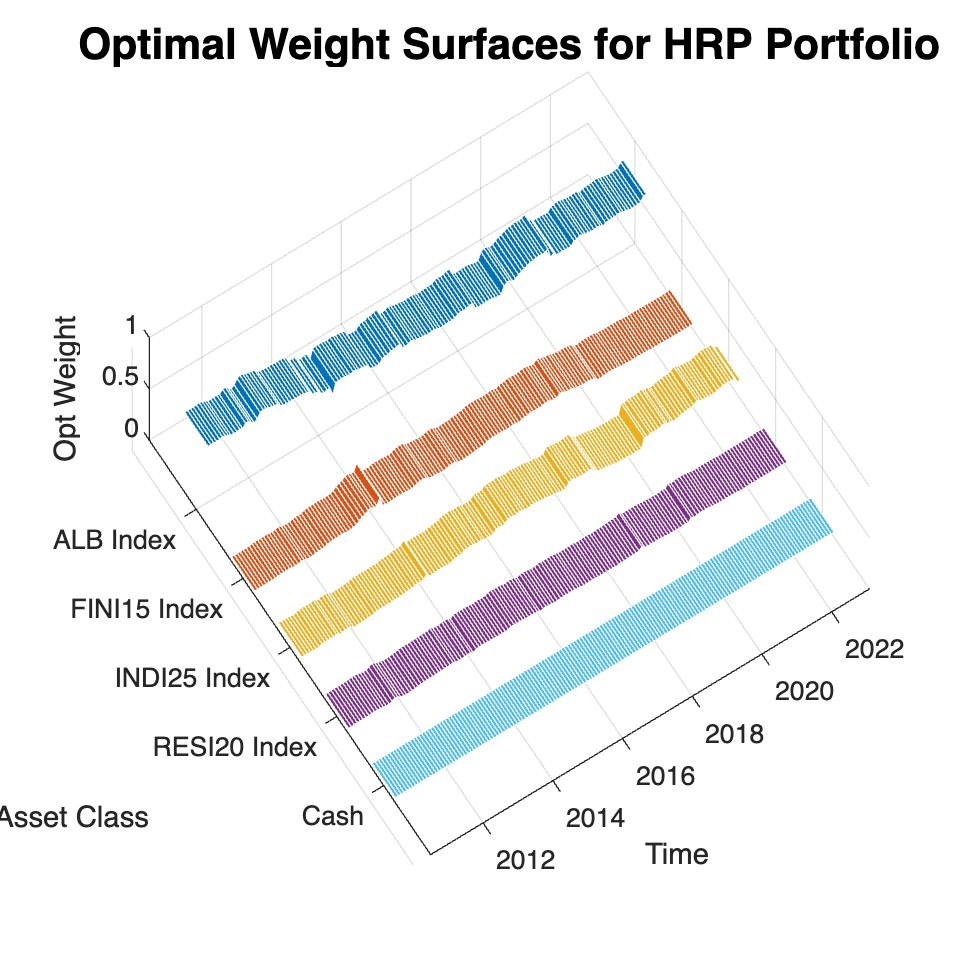

W_sd = 2;
Return_matrix = table2array(M_Ret_TT);
[wx,b,ui,li] = winsorise(Return_matrix,W_sd);
winsorisedRet_TT = array2timetable(wx,'RowTimes',M_Ret_TT.Time);

winsorisedRet_TT.Properties.VariableNames = M_Ret_TT.Properties.VariableNames;


ans = 5×5 table
                   Ann.Return    Ann.Risk       SR       Ann.SR      PSR  
                   __________    ________    ________    ______    _______

    EW               0.10758     0.096754     0.13531    1.6581    0.99976
    MV               0.10177      0.12291    0.094345    1.1532    0.99612
    BalFun (BH)      0.11233      0.10081     0.14216    1.7454    0.99979
    HRP             0.097027     0.081515     0.12676    1.5464    0.99963
    BalFun (CM)      0.11143     0.094951     0.14845     1.822    0.99988


test_class2 = backtestedPortfolios;
HSFPparameters_test = HSFPparameters;
test_class2.HSFPparameters = HSFPparameters_test;
test_class2.Returns = winsorisedRet_TT;
test_class2.Method =  'none';
test_class2.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class2.HRPcashConstriant = 1;
test_class2.MVWts_lb = [0 0 0 0 0.05];
test_class2.MVWts_ub = [1 1 1 1 0.05];
test_class2.RegLambda = 0.005;

 test2_bcktest = OOPbacktest_analysis(test_class2)
backtestPlot(test2_bcktest)

test2_bcktest.Attributions

returns_st1 = test_bcktest.Realised_tsPRet_TT.HRP; 
SIZE = numel(returns_st1);

% Create a histogram
histogram(returns_st1, SIZE/2, 'FaceColor', 'red');
title('Strategy 1 returns distribution');


test2_bcktest =   backtestedPortfolios with properties:

        PortfoliosList: {'EW (CM)'  'MVSR max'  'BalFund (BH)'  'HRP'  'BalFund (CM)'  'ALSI'  'ALBI'  'Cash'}
             AssetList: {'ALB_Index'  'FINI15_Index'  'INDI25_Index'  'RESI20_Index'  'Cash'}
          Attributions: [5×5 table]
    RollingPerformance: [152×8 timetable]
              HSFP_Prs: []
         NumPortfolios: 0
              DataType: "backtestedPortfolios"
         ExcessReturns: [151×5 double]
           GeometricSR: [1.9534 1.6976 1.9619 2.0518 2.0690]
            OptPortWts: {2×5 cell}
    Realised_tsPRet_TT: [152×8 timetable]
          WindowLength: 36
               Returns: [188×6 timetable]
               Signals: [189×1 timetable]
             RegLambda: 0.0050
              MVWts_lb: [0 0 0 0 0.0500]
              MVWts_ub: [1 1 1 1 0.0500]
     HRPcashConstriant: 1
                Method: "none"
        HSFPparameters: [

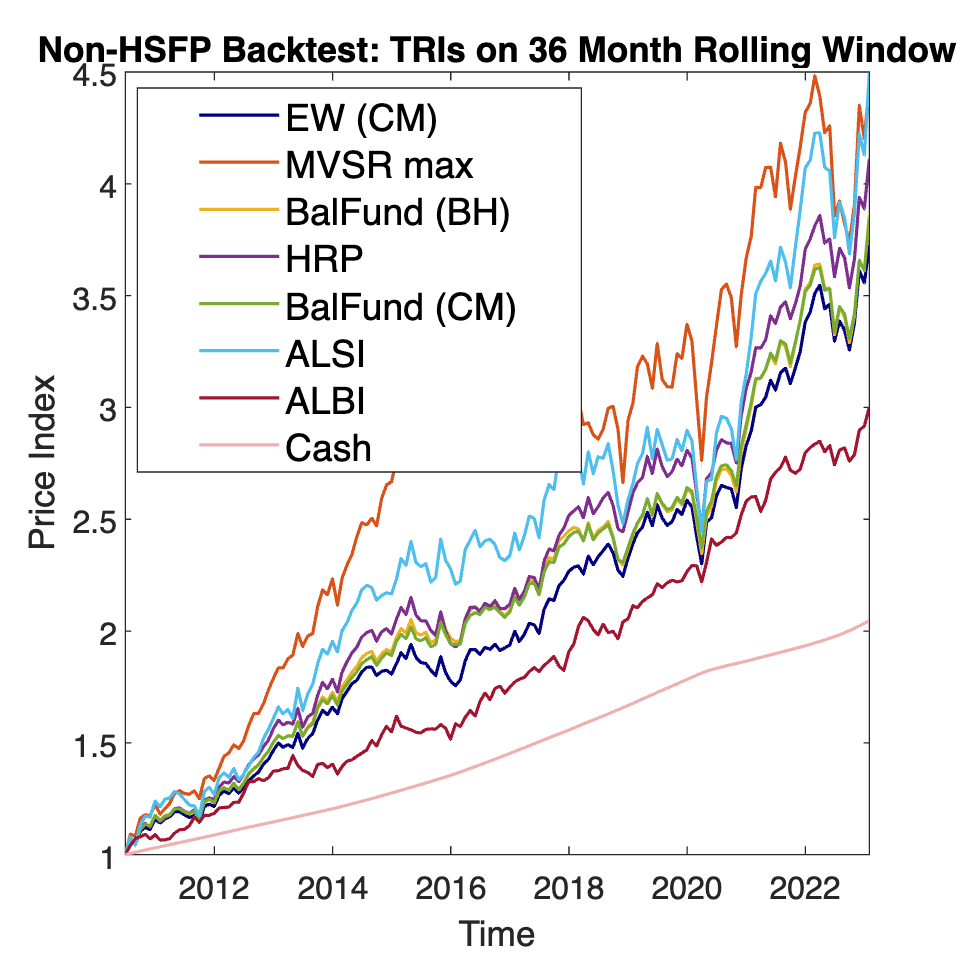

ans =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [1 1 1]
    Position: [100 100 600 600]
       Units: 'pixels'

  Show all properties


% Overlay the kernel density estimate

hold on;
[f, xi] = ksdensity(returns_st1);

ans = 5×5 table
                   Ann.Return    Ann.Risk        SR         Ann.SR       PSR  
                   __________    _________    _________    ________    _______

    EW               0.11028      0.086647      0.15924      1.9534    0.99999
    MV              0.060174      0.064782    0.0066565    0.079933    0.99947
    BalFun (BH)      0.11336       0.09141      0.15972      1.9619    0.99998
    HRP             0.058687     0.0034861      0.18039      2.1648          1
    BalFun (CM)      0.11298      0.086065      0.16847       2.069    0.99999


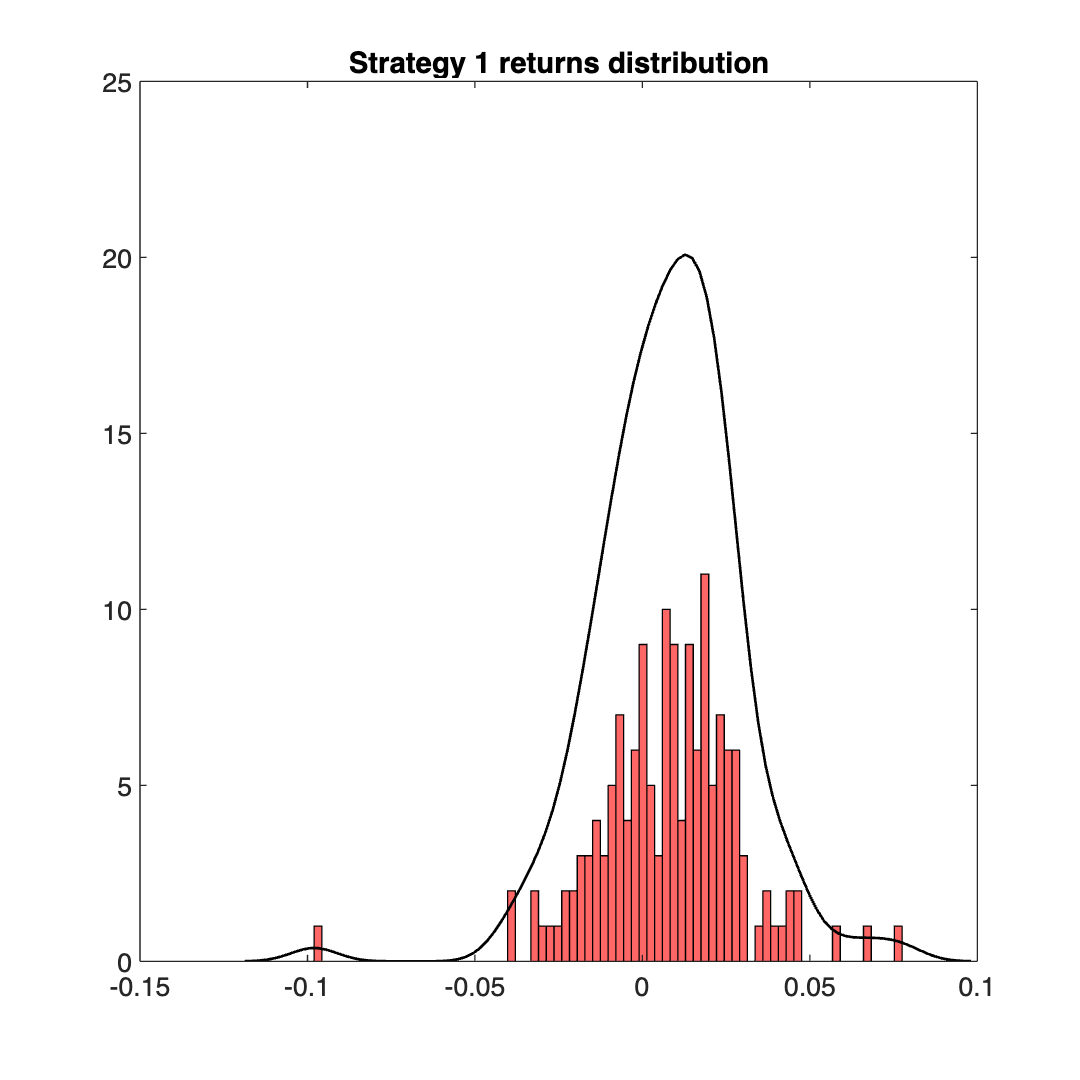

plot(xi, f, 'LineWidth', 1, 'Color', 'k');
hold off;